tic
clc;clear all

fprintf('待分析點雲\r\n');

待分析點雲


cla_data = open_and_importdata('D:\論文\1080919\FULL\20210415\frame_based\C5\1F');
cla_data = cla_data(:,1:3)

cla_data =     3.7281    3.8863    1.5960
    3.6273    3.9227    0.8602
    3.6013    3.8748    0.8602
    3.6072    3.8820    0.8705
    3.5986    3.8800    0.8685
    3.5922    3.8737    0.8641
    3.6046    3.8666    0.8525
    3.6297    3.8967    0.8559
    3.6491    3.8958    0.8677
    3.6508    3.8918    0.8594




%% 計算各點代表之直線向量

cla_r = 0.05; %閥值
cla_N_point = size(cla_data,1); %point_number


for cla_ii1 = 1:1:cla_N_point
    p = ones(cla_N_point,3)*[cla_data(cla_ii1,1) , 0 , 0 ; 0 , cla_data(cla_ii1,2) , 0 ; 0 , 0 , cla_data(cla_ii1,3)]; %選取點之座標
    D = sum((cla_data - p).^2,2).^(0.5); %最小二乘法
    aaa = find(D <= cla_r);
    cla_x = cla_data(aaa,1) ;
    cla_y = cla_data(aaa,2) ;
    cla_z = cla_data(aaa,3) ;
    
    [nx,mx] = size(cla_x); %求取aaa之行列數
    cla_m(cla_ii1,:) = [mean(cla_x),mean(cla_y),mean(cla_z)]; %找出目標點之X座標，Y座標，Z座標平均
    cla_w = [cla_x-cla_m(cla_ii1,1),cla_y-cla_m(cla_ii1,2),cla_z-cla_m(cla_ii1,3)]; % Use "mean" point as base
    cla_q = (1/nx)*cla_w'*cla_w; % 'q' is a positive definite matrix
    [cla_u,cla_d,cla_v] = svd(cla_q); % 'eig' & 'svd' get same eigenvalues for this matrix
    cla_p(cla_ii1,:) = cla_u(:,1)'; % Get eigenvector for largest eigenvalue
    cla_s(cla_ii1,:) = cla_d(2,2)+cla_d(3,3); % Sum the other two eigenvalues
end

cla_data(:,4) = zeros(cla_N_point,1)

cla_data =     3.7281    3.8863    1.5960         0
    3.6273    3.9227    0.8602         0
    3.6013    3.8748    0.8602         0
    3.6072    3.8820    0.8705         0
    3.5986    3.8800    0.8685         0
    3.5922    3.8737    0.8641         0
    3.6046    3.8666    0.8525         0
    3.6297    3.8967    0.8559         0
    3.6491    3.8958    0.8677         0
    3.6508    3.8918    0.8594         0


aaa_x = find(abs(cla_p(:,1))>abs(cla_p(:,2))&abs(cla_p(:,1))>abs(cla_p(:,3)));
aaa_y = find(abs(cla_p(:,2))>abs(cla_p(:,1))&abs(cla_p(:,2))>abs(cla_p(:,3)));
aaa_z = find(abs(cla_p(:,3))>abs(cla_p(:,2))&abs(cla_p(:,3))>abs(cla_p(:,1)));
%填入第四行(X向=1,Y向=2,Z向=3)
cla_data(aaa_x,4) = ones(size(aaa_x))*1;
cla_data(aaa_y,4) = ones(size(aaa_y))*2;
cla_data(aaa_z,4) = ones(size(aaa_z))*3;

% save data2.mat cla_data 

% load data2.mat
cla_point_number = size(cla_data,1);
% 
% floor_number = 2;%樓層數
% first_floor_height = 2.1;%一樓高
% beam_height = 0.25;%梁深
% floor_height = 1.5;%樓高
noise = [];
for Point_number = 1:cla_point_number
    if cla_data(Point_number,4)==1
        
        if cla_data(Point_number,3)<1
            noise = [noise ;Point_number];
        end
%         for i = 0:1:floor_number-1
%             if cla_data(Point_number,3)>first_floor_height+i*floor_height && cla_data(Point_number,3)<first_floor_height+i*floor_height+beam_height
%                 noise = [noise ;Point_number];
%             end
%         end
    end
    if cla_data(Point_number,4)==2
        
        if cla_data(Point_number,3)<1
            noise = [noise ;Point_number];
        end
%         for i = 0:1:floor_number-1
%             if cla_data(Point_number,3)>first_floor_height+i*floor_height && cla_data(Point_number,3)<first_floor_height+i*floor_height+beam_height
%                 noise = [noise ;Point_number];
%             end
%         end
    end
end
c=0;
for i = 1: size(noise)
    cla_data(noise(i)-c,:)=[];
    c=c+1;
end


db_data = db_classify_function_SHAKE2(cla_data)%% 先以DB-Scan消除雜訊，再以各群集標準差判定是否為直線群集

db_data =     3.7281    3.8863    1.5960    3.0000    1.0000
    3.6764    3.8759    0.8707    3.0000    1.0000
    3.6684    3.8737    0.8678    3.0000    1.0000
    3.6758    3.8767    0.9938    3.0000    1.0000
    3.6455    3.9029    0.9023    3.0000    1.0000
    3.6660    3.8780    0.8849    3.0000    1.0000
    3.6673    3.8749    0.8766    3.0000    1.0000
    3.6593    3.8722    0.9141    3.0000    1.0000
    3.6668    3.8759    0.9117    3.0000    1.0000
    3.6588    3.8735    0.9229    3.0000    1.0000


dbnn_data = db_data(find(db_data(:,5)~=-1),:) %提取非噪點

dbnn_data =     3.7281    3.8863    1.5960    3.0000    1.0000
    3.6764    3.8759    0.8707    3.0000    1.0000
    3.6684    3.8737    0.8678    3.0000    1.0000
    3.6758    3.8767    0.9938    3.0000    1.0000
    3.6455    3.9029    0.9023    3.0000    1.0000
    3.6660    3.8780    0.8849    3.0000    1.0000
    3.6673    3.8749    0.8766    3.0000    1.0000
    3.6593    3.8722    0.9141    3.0000    1.0000
    3.6668    3.8759    0.9117    3.0000    1.0000
    3.6588    3.8735    0.9229    3.0000    1.0000


%  dbnn_data = sort(dbnn_data(:,5));
db_times = 3;%幾個標準差
db_check = zeros(size(dbnn_data,1),1);%點數
db_group = zeros(max(dbnn_data(:,5)),3);%群數
db_group(:,2) =1:1:max(dbnn_data(:,5));
%找噪點 非噪點 check=1 group=0;噪點 check=-1 group=-1
for db_ii1 = 1:max(dbnn_data(:,5))%未達設定之標準差則判定為噪點
    aaa = find(dbnn_data(:,5)==db_ii1);
    db_std(db_ii1,1:3) = std(dbnn_data(aaa,1:3));
    if dbnn_data(aaa(1,1),4) == 1
        db_group(db_ii1,1) = 1;
        if db_std(db_ii1,1)/db_std(db_ii1,2) >= db_times && db_std(db_ii1,1)/db_std(db_ii1,3) >= db_times
            db_check(aaa,1) = ones(size(aaa));
            db_group(db_ii1,3) = 0;
        else
            db_check(aaa,1) = ones(size(aaa))*-1
            db_group(db_ii1,3) = 1;
        end
    elseif dbnn_data(aaa(1,1),4) == 2
        db_group(db_ii1,1) = 2;
        if db_std(db_ii1,2)/db_std(db_ii1,1) >= db_times && db_std(db_ii1,2)/db_std(db_ii1,3) >= db_times
            db_check(aaa,1) = ones(size(aaa));
            db_group(db_ii1,3) = 0;
        else
            db_check(aaa,1) = ones(size(aaa))*-1
            db_group(db_ii1,3) = 1;
        end
    elseif dbnn_data(aaa(1,1),4) == 3
        db_group(db_ii1,1) = 3;
        if db_std(db_ii1,3)/db_std(db_ii1,1) >= db_times && db_std(db_ii1,3)/db_std(db_ii1,2) >= db_times
            db_check(aaa,1) = ones(size(aaa));
            db_group(db_ii1,3) = 0;
        else
            db_check(aaa,1) = ones(size(aaa))*-1
            db_group(db_ii1,3) = 1;
        end
    end
end

aaa = find(db_check(:,1)~=-1);
dbfi_data = dbnn_data(aaa,:);
aaa = find(db_group(:,3)~=-1);
dbnn_group = db_group(aaa,:);
dbnn_group = db_group(aaa,:);
c = 1;
for db_ii2 = dbnn_group(:,2)'
    aaa = find(dbfi_data(:,5)==db_ii2);
    db_mp(c,1:3) = mean(dbfi_data(aaa,1:3));
    c=c+1;
end
c = 1;
db_lim = 0.01;%與平均相差超過閥值則判定為噪點
for db_ii3 = 1:1:3
    dbn = find(dbnn_group(:,1)==db_ii3);
    for db_ii4 = dbn'
        if dbnn_group(db_ii4,3) == 0
            aaa = ones(size(dbn,1),3)*[db_mp(db_ii4,1) , 0 , 0 ; 0 ,db_mp(db_ii4,2) , 0 ; 0 , 0 , db_mp(db_ii4,3)];
            aaa1 = db_mp(dbn,:) - aaa;
            if db_ii3 == 1
                aaa2 = find(abs(aaa1(:,2))<=db_lim & abs(aaa1(:,3))<=db_lim);
                for db_ii5 = dbn(aaa2)'
                    if dbnn_group(db_ii5,3) == 0
                        dbnn_group(db_ii5,3) = c;
                    else
                    end
                end
            elseif db_ii3 == 2
                aaa2 = find(abs(aaa1(:,1))<=db_lim & abs(aaa1(:,3))<=db_lim)
                for db_ii5 = dbn(aaa2)'
                    if dbnn_group(db_ii5,3) == 0
                        dbnn_group(db_ii5,3) = c
                    else
                    end
                end
            elseif db_ii3 == 3
                aaa2 = find(abs(aaa1(:,1))<=db_lim & abs(aaa1(:,2))<=db_lim);
                for db_ii5 = dbn(aaa2)'
                    if dbnn_group(db_ii5,3) == 0
                        dbnn_group(db_ii5,3) = c;
                    else
                    end
                end
            end
            c = c+1
        else
        end
    end
end

c = 2

c = 3

c = 4

c = 5

c = 6

c = 7

c = 8


c = 1

c = 1

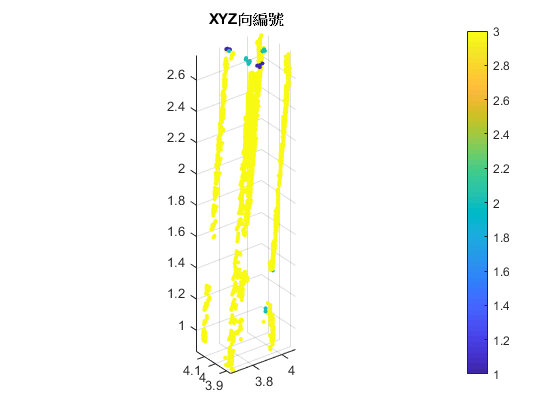

for fi_ii1 = dbnn_group(:,2)'
    aaa = find(dbfi_data(:,5) == fi_ii1);
    group_N(fi_ii1,1) = size(aaa,1);
    dbfi_data(aaa,5) = ones(size(aaa))*dbnn_group(c,3);
    c=c+1;
end

group_num = max(dbfi_data(:,5));
group_mean = zeros(group_num,4);

for i = 1:1:group_num
    group_chk = dbfi_data(find(dbfi_data(:,5)==i),:);
    
    if group_chk(:,4) == 3
        meanALL = mean(group_chk,1);%算出XYZ座標平均
        mean_X = meanALL(1);
        mean_Y = meanALL(2);
        mean_Z = 0;
    elseif group_chk(:,4) == 2
        meanALL = mean(group_chk,1);
        mean_X = meanALL(1);
        mean_Y = 0;
        mean_Z = meanALL(3);
    elseif group_chk(:,4) == 1
        meanALL = mean(group_chk,1);
        mean_X = 0;
        mean_Y = meanALL(2);
        mean_Z = meanALL(3);
    end
    
    group_mean(i,1)=i;
    group_mean(i,2)=mean_X;
    group_mean(i,3)=mean_Y;
    group_mean(i,4)=mean_Z;
end
dist3 =  0.1;%XY平均值差異
if group_chk(:,4) ~=3
    for i=1:group_num
        for j=i+1:group_num
            if abs(group_mean(i,2)-group_mean(j,2))<= dist3 && abs(group_mean(i,3)-group_mean(j,3))<= dist3 && abs(group_mean(i,4)-group_mean(j,4))<= dist3
                group_mean(j,1)=group_mean(i,1);
            end
        end
    end
    
elseif group_chk(:,4) ==3
    dist4 = 0.15; %XY平均值差異
    ratio_difference = 0.1; %XY向斜率差異
    for i=1:group_num
        for k=i+1:group_num
            if abs((group_mean(i,2)-group_mean(k,2)))<= dist4 && abs(group_mean(i,3)-group_mean(k,3))<= dist4
                group_mem1 = find(dbfi_data(:,5)==i);
                group_mem2 = find(dbfi_data(:,5)==k);
                N1 = max(size(group_mem1));
                N2 = max(size(group_mem2));
                x_ratio_1 = abs((dbfi_data(group_mem1(1),1)-dbfi_data(group_mem1(N1),1)))/abs(dbfi_data(group_mem1(1),3)-dbfi_data(group_mem1(N1),3));
                y_ratio_1 = abs((dbfi_data(group_mem1(1),2)-dbfi_data(group_mem1(N1),2)))/abs(dbfi_data(group_mem1(1),3)-dbfi_data(group_mem1(N1),3));
                x_ratio_2 = abs((dbfi_data(group_mem2(1),1)-dbfi_data(group_mem2(N2),1)))/abs(dbfi_data(group_mem2(1),3)-dbfi_data(group_mem2(N2),3));
                y_ratio_2 = abs((dbfi_data(group_mem2(1),2)-dbfi_data(group_mem2(N2),2)))/abs(dbfi_data(group_mem2(1),3)-dbfi_data(group_mem2(N2),3));
                if  abs(x_ratio_1-x_ratio_2) < ratio_difference && abs(y_ratio_1-y_ratio_2) < ratio_difference
                    group_mean(k,1)=group_mean(i,1);
                end
            end
        end
    end
end

%  clear dist4 ratio_difference group_mem1 group_mem2 x_ratio_1 x_ratio_2 y_ratio_1 y_ratio_2 mean_X mean_Y mean_Z

for i=1:group_num
    samegroup = find(dbfi_data(:,5)==i);
    for j=1:size(samegroup)
        dbfi_data(samegroup(j),5)=group_mean(i,1);
    end
end
new_group=[];
for i=1:max(dbfi_data(:,5))
    new_group_num = find(dbfi_data(:,5)==i);
    if size(new_group_num)~=0
        new_group(i,:) = dbfi_data(new_group_num(1,1),:);
    end
end
new_group(all(new_group==0,2),:)=[];
for i=1:size(new_group)
    new_group(i,6)=i;
end
new_group_data=[];
for i=1:size(new_group)
    new_group_data = find(dbfi_data(:,5)==new_group(i,5));
    dbfi_data(new_group_data(:,1),5)=new_group(i,6);
end


figure(1)
scatter3(db_data(:,1),db_data(:,2),db_data(:,3),10,db_data(:,4),'filled')
title('XYZ向編號');
colorbar
axis equal

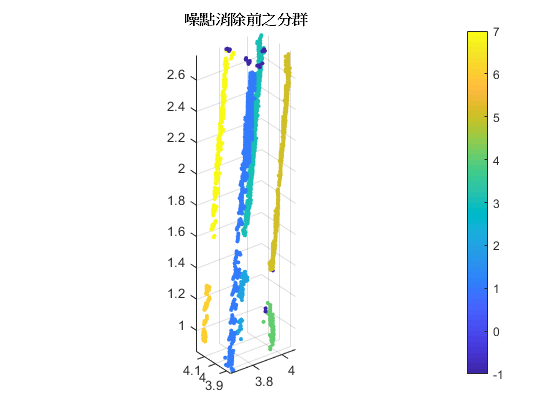


figure(2)
scatter3(db_data(:,1),db_data(:,2),db_data(:,3),10,db_data(:,5),'filled')
title('噪點消除前之分群');
colorbar
axis equal

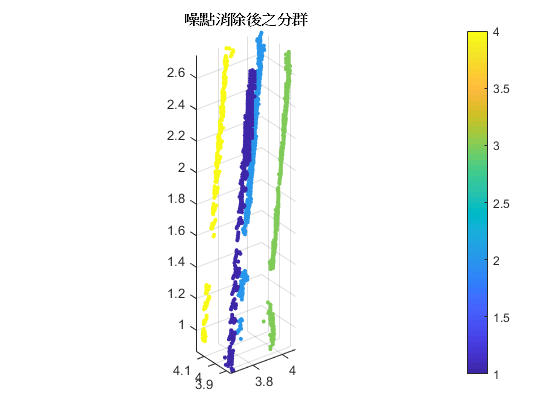


figure(3)
scatter3(dbfi_data(:,1),dbfi_data(:,2),dbfi_data(:,3),10,dbfi_data(:,5),'filled')
title('噪點消除後之分群');
colorbar
axis equal


c = 1;
for i = 1:1:max(dbfi_data(:,5))
    bbb = find(dbfi_data(:,5)==i)
    group_N(i,2) = size(bbb,1)
end

bbb =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


group_N =    434   434
    55     0
   303     0
    71     0
   309     0
    59     0
   208     0


bbb =    110
   111
   112
   113
   114
   115
   116
   117
   118
   119


group_N =    434   434
    55   358
   303     0
    71     0
   309     0
    59     0
   208     0


bbb =    145
   146
   147
   148
   149
   150
   151
   152
   153
   154


group_N =    434   434
    55   358
   303   380
    71     0
   309     0
    59     0
   208     0


bbb =    557
   558
   559
   560
   561
   562
   563
   564
   565
   566


group_N =    434   434
    55   358
   303   380
    71   267
   309     0
    59     0
   208     0



group_number_finish = max(dbfi_data(:,5));

%     save data_shake_db3.mat dbfi_data
%     dlmwrite('G:\論文\1080919\DB_SHAKE2\DB_SHAKE_Finish.txt',dbfi_data,'delimiter',' ','newline', 'pc')
%  xlswrite('D:\論文\1080919\FULL\20210415\BEAM\B13\6F\B13_6F_DB.xlsx',dbfi_data)

toc

Elapsed time is 5.640044 seconds.
